# **Assignment:  Feature Classification  of CWRU Dataset**

**Name: Joungbin Choi  **

**Student ID: 22200757**

**Data: 2025/11/24**

## **Introduction**

**Due in 1 week.**

1. **Read the paper and understand the whole process**

This Assignment is implementation a part of classification in the literature 

- Rauber, T. W., de Assis Boldt, F., & Varejao, F. M. (2015, January). Heterogeneous Feature Models and Feature Selection Applied to Bearing Fault Diagnosis. *IEEE Transactions on Industrial Electronics*. Institute of Electrical and Electronics Engineers (IEEE).

**2. Apply KNN and SVM  classification methods with all  features **

**3. Apply KNN and SVM  classification methods with Selected features by Forward/Backward eliminiation**

- Read here: [https://kr.mathworks.com/help/stats/sequentialfs.html](https://kr.mathworks.com/help/stats/sequentialfs.html)

**4. Apply KNN and SVM  classification with Reduce feature dimension by PCA or LDA**

- Read here:  https://kr.mathworks.com/help/stats/pca.html?lang=en

You have to show necessary steps and plots/data with proper comments

Which gives the best evaluation performance on Test set? Also try to optimize KNN and SVM

## Dataset

**Given: Feature Extracted from CWRU bearing dataset **

You are provided with train and test dataset consists of CWRU data features. 

Download a selected sample of  CWRU Dataset ([**download here**](https://github.com/ykkimhgu/HGU_IAIA/tree/main/Dataset/CWRU_selected_dataset))

- Download   **Feature_data.zip**  

- `/Dataset/CWRU_selected_dataset/Feature_data/`

It should be located in your local folder of

- `/Dataset/CWRU_selected_dataset/Feature_data/`

You can refer to the previous Assignment: FeatureExtraction CWRU `IAIA_Assignment_CWRU_FeatureExtraction_student.mlx`

Classes:

-  Normal / Outer Race fault / Inner Race fault / Ball fault

The given data is divided by Train set and Test set 

**Note**

Training. K-fold, cross-validation is performed on Train Dataset only.

Test dataset is used for Evaluation.

## Load Dataset

close all
clear



% Train set
trainset = load("../IAIA/Dataset/CWRU_selected_dataset/Feature_data/sample_train.mat");
% load("sample_train.mat");
X_train = table2array(trainset.glob_all_train);
Y_train = categorical(trainset.class_cwru_train);

% Test set
testset = load("../IAIA/Dataset/CWRU_selected_dataset/Feature_data/sample_test.mat");
% load("sample_test.mat");
X_test = table2array(testset.glob_all_test);     
Y_test = categorical(testset.class_cwru_test); 

## **Section 1: Classification with all features**

You need to explain the process cleary and analyze the results

**Classfier 1: SVM**

For multi-class SVM, use      **fitcecoc( )**

[https://kr.mathworks.com/help/stats/fitcecoc.html?lang=en](https://kr.mathworks.com/help/stats/fitcecoc.html?lang=en)

fitcecoc는 fit Catergorical ECOC classifier이다. 다중 클래스 문제를 여러 개의 이진 분류 문제로 분해하고 학습

이는 여러 이진 분류의 결과를 조합하기에 안정성을 증가시킨다.

Feature들의 스케일을 맞춰주기 위해 standardize를 true로 설정

t = templateSVM('KernelFunction','rbf','BoxConstraint', 1, 'Standardize', true);
cv = cvpartition(Y_train, 'KFold', 10);
% Train full model directly
mdl_svm = fitcecoc(X_train, Y_train, 'Learners', t, 'ClassNames', {'normal','inner','outer'});

### Analyze (Train Data)

Resubsitution Error: 모델 학습에 사요된 데이터로 다시 성능을 확인하는 과정에서 나온 오차

mlResubErr = resubLoss(mdl_svm);
fprintf('mlResubErr: %d', mlResubErr);

Resubsitution Predict: 재대입 예측

mlClass = resubPredict(mdl_svm);

confusionchart(Y_train, categorical(mlClass));
title("SVM Confusion Matrix with Train Data");

사용된 데이터를 다시 모델에 입력하여 성능을 측정했을 때 에러값 0으로 잘 학습이 됐다 생각할 수 있지만 과적합 위험성이 있기에 cross validation과 test dataset으로 다시 한번 검증이 필요하다.

### CV Validation

데이터를 10개로 나눠서 cross validation. 9개로 학습하고 1개로 검증하는 과정을 반복.

svm_cross_val= crossval(mdl_svm,'CVPartition',cv);
svmCVError = kfoldLoss(svm_cross_val);
fprintf('svmCVError: %f', svmCVError);
svm_accuracy = 1- svmCVError;
fprintf('svm_accuracy: %f%%', svm_accuracy*100);
svm_cv_pred = kfoldPredict(svm_cross_val);
confusionchart(Y_train, categorical(svm_cv_pred));
title("SVM Confusion Matrix of CV")

교차 검증 결과, 87.27%의 정확도와 0.125의 에러값으로 보다 낮은 정확도가 나왔다. 

### Predict with Test Data

학습과 검증에 사용되지 않은 raw한 데이터로 테스트를 진행하였다.

[svm_pred_test, ~] = predict(mdl_svm, X_test);
svm_test_err = loss(mdl_svm, X_test, Y_test);
fprintf('svm_test_err: %f', svm_test_err);

svm_test_acc = sum(svm_pred_test == Y_test) / numel(Y_test);
fprintf('svm_test_acc: %f%%', svm_test_acc*100);

confusionchart(Y_test, categorical(svm_pred_test));

mlResubErr: 0

title("SVM Confusion Matrix with Test Data");

91.66%의 정확성과 0.083의 에러값으로 준수한 성능이 나왔다.

[~, score] = pca(X_test);
xyz = score(:, 1:3); 

figure; 
hold on; grid on;
classes = categories(Y_test);
colors = lines(length(classes)); 

for i = 1:length(classes)
    idx = (Y_test == classes{i});

svmCVError: 0.122685

    scatter3(xyz(idx,1), xyz(idx,2), xyz(idx,3), 30, colors(i,:), 'filled', ...
        'DisplayName', string(classes{i}));

svm_accuracy: 87.731481%

end

idx_err = (Y_test ~= svm_pred_test);
if sum(idx_err) > 0
    scatter3(xyz(idx_err,1), xyz(idx_err,2), xyz(idx_err,3), ...
        100, 'r', 'x', 'LineWidth', 2, 'DisplayName', 'Misclassified');
end

legend('Location', 'best');

svm_test_err: 0.083333

title('SVM Test Result: Colored by True Class (X=Error)');
view(3); hold off;

Test data로 모델을 평가했을 때 나온 결과 값이다. 잘못 classification된 값은 x모양으로 표시하였다.

### **Classifier 2: KNN**

K-Nearest Neighbors로 classification을 진행하였다.

파라미터 값인 K값은 optimized하기 위해 auto 모드로 하였다.

mdl_knn = fitcknn(X_train,Y_train,'OptimizeHyperparameters','auto',...

svm_test_acc: 91.666667%

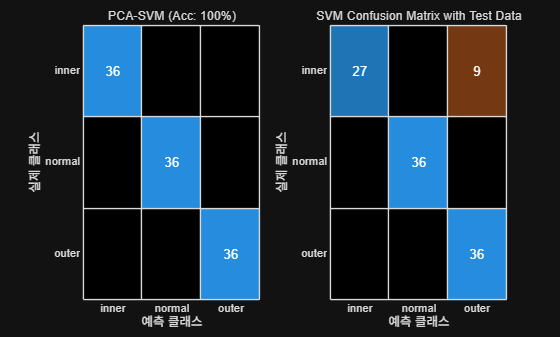

    'HyperparameterOptimizationOptions',...
    struct('AcquisitionFunctionName','expected-improvement-plus'))
trainloss = resubLoss(mdl_knn);

fprintf('trainloss: %d', trainloss);

#### Analyze Train Data

mlClass_train = resubPredict(mdl_knn);
confusionchart(Y_train, mlClass_train);
title("KNN Confusion Matrix with Train Data")

SVM과 똑같이 학습에 사용된 데이터를 resub 함수로 사용하였을 때 에러값 0으로 좋은 결과지만 과적합 문제가 있을 수 있는 결과값이 나왔다.

cv = cvpartition(Y_train, 'KFold', 10);
cross_val_knn = crossval(mdl_knn, 'CVPartition', cv);
knnCVError = kfoldLoss(cross_val_knn);
fprintf('knnCVError: %d', knnCVError);
knn_accuracy = 1 - knnCVError;
fprintf('knn_accuracy: %d', knn_accuracy*100);

knn_cv_pred = kfoldPredict(cross_val_knn);
confusionchart(Y_train, categorical(knn_cv_pred));
title("KNN Confusion Matrix of CV")

교차 검증에서도 100% 정확성이 나왔다.

### Predict with Test Data

[knn_pred_test, ~] = predict(mdl_knn, X_test);
testloss = loss(mdl_knn, X_test, Y_test);
fprintf('testloss: %d', testloss);
knn_test_acc = sum(knn_pred_test == Y_test) / numel(Y_test);
fprintf('knn_test_acc: %d%%', knn_test_acc*100);
confusionchart(Y_test, knn_pred_test);
title("KNN Confusion Matrix with Test Data");

KNN을 사용 했을 때 학습된 모델을 test dataset으로 검증해도 100%의 정확성이 나온다. 

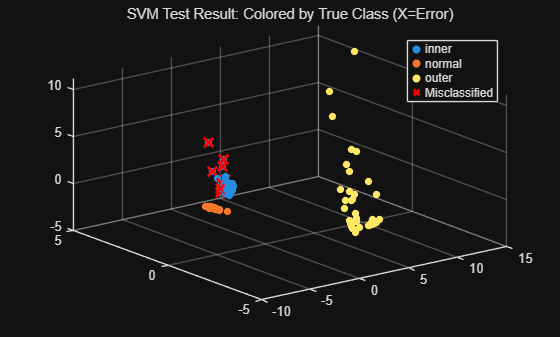

figure; 
hold on; grid on;

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | NumNeighbors |     Distance |  Standardize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |     0.66435 |     0.10457 |     0.66435 |     0.66435 |           92 |  mahalanobis |        false |
|    2 | Best   |           0 |    0.079712 |           0 |    0.026415 |          122 |     spearman |         true |
|    3 | Accept |           0 |     0.03636 |           0 |    0.013499 |            6 |       cosine |         true |
|    4 | Accept |           0 |    0.036727 |           0 |   0.0090729 |           12 |    cityblock |        false |
|    5 | Accept |           0 |    0.040603 |   

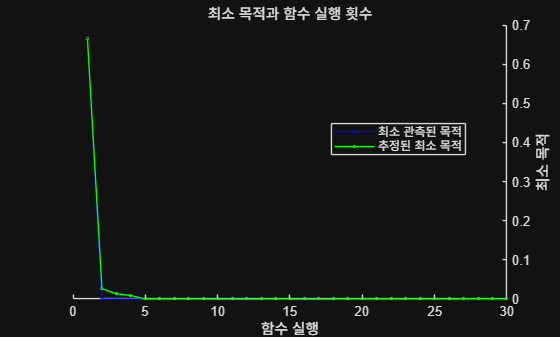

mdl_knn =   ClassificationKNN
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [inner    normal    outer]
                       ScoreTransform: 'none'
                      NumObservations: 432
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                             Distance: 'seuclidean'
                         NumNeighbors: 35


  Properties, Methods



for i = 1:length(classes)
    idx = (Y_test == classes{i});
    scatter3(xyz(idx,1), xyz(idx,2), xyz(idx,3), 30, colors(i,:), 'filled', ...
        'DisplayName', string(classes{i}));
end

idx_err_knn = (Y_test ~= knn_pred_test); 

if sum(idx_err_knn) > 0
    scatter3(xyz(idx_err_knn,1), xyz(idx_err_knn,2), xyz(idx_err_knn,3), ...

trainloss: 0

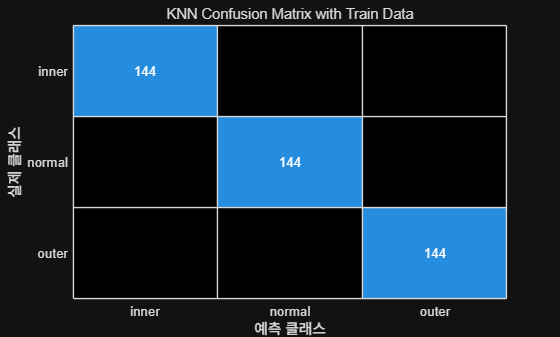

        100, 'k', 'x', 'LineWidth', 2, 'DisplayName', 'Misclassified');
end

legend('Location', 'best');

title('KNN Test Result: Colored by True Class (X=Error)');
view(3); hold off;

테스트 데이터셋을 KNN으로 clasificaiton한 결과값을 시각화 하였다. 잘못 나온 값이 없음을 볼 수 있다.

## **Section 2: Classification on Selected features**

Wrapper Type Feature Selection: Sequential Feature Selection

**Use  :  **`inmodel = sequentialfs(fun,X,y)`

`backward 혹은 forward를 사용하여 SFS를 하여 feature selection을 진행하고 결과를 보았다.`

lossfun = 'mincost';
opts = statset('Display', 'iter'); 
dir = 'backward';

knnCVError: 0

% dir = 'forward';


knn_accuracy: 100

fun_svm = @(XT,yT,Xt,yt) loss(fitcecoc(XT,yT), Xt, yt, 'Lossfun', lossfun);
[inmodel_svm, history_svm] = sequentialfs(fun_svm, X_train, Y_train, 'CV', cv, 'options', opts, 'direction', dir);

최종 선택된 feature idx

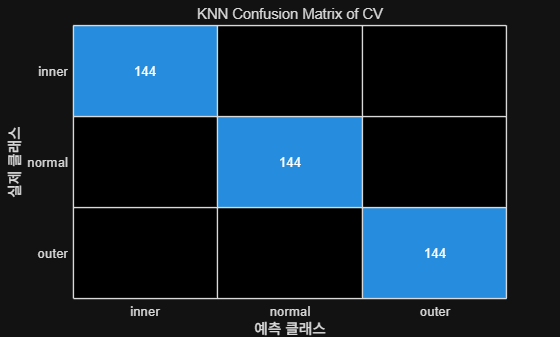

svm_idx_select = find(inmodel_svm)
svm_train_select    = X_train(:, svm_idx_select);

svm_test_select     = X_test(:, svm_idx_select);

svm_mdl_select  = fitcecoc(svm_train_select, Y_train);
svm_cv_select   = crossval(svm_mdl_select);


testloss: 0


fprintf('Accuracy of SVM with all features: %f%%', svm_accuracy*100)

knn_test_acc: 100%

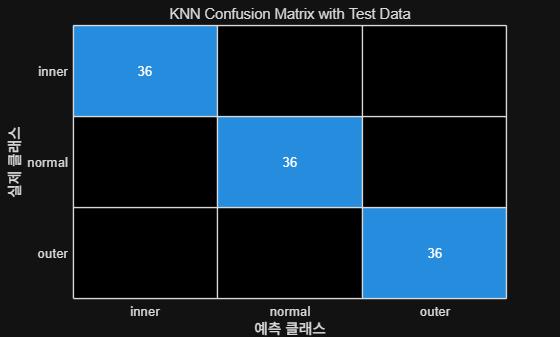


svm_accuracy_select = 1 - kfoldLoss(svm_cv_select);

fprintf('Accuracy of SVM with selected features: %d%%', svm_accuracy_select*100)

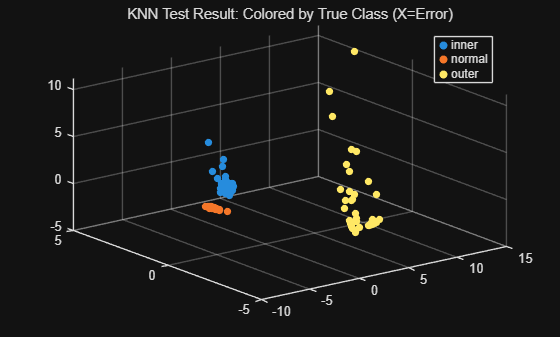

lossfun = 'mincost';
opts = statset('Display', 'iter'); 
dir = 'backward';
% dir = 'forward';
k = 6; 

fun_knn = @(XT,yT,Xt,yt) loss(fitcknn(XT,yT, 'NumNeighbors', k, 'Standardize', true), Xt, yt, 'Lossfun', lossfun);

[inmodel_knn, history_knn] = sequentialfs(fun_knn, X_train, Y_train, 'CV', cv, 'options', opts, 'direction', dir);
knn_idx_select = find(inmodel_knn)
knn_train_select    = X_train(:, knn_idx_select);
knn_test_select     = X_test(:, knn_idx_select);

knn_mdl_select  = fitcknn(knn_train_select, Y_train, 'NumNeighbors', k, 'Standardize', true);
knn_cv_select   = crossval(knn_mdl_select);

fprintf('Accuracu of KNN with all features: %d%%', knn_accuracy*100);
fprintf('Accuracu of KNN with selected features: %d%%', knn_accuracy_select*100);

## **Section 3: Classification on Reduced Features**

**Use: **[`coeff = pca(X)`](https://kr.mathworks.com/help/stats/pca.html?lang=en#d123e644629)`, `[`coeff = pca(X,Name,Value)`](https://kr.mathworks.com/help/stats/pca.html?lang=en#d123e644661)

정규화를 위해 zscore 사용

[X_train_std, mu, sigma] = zscore(X_train);
X_test_std = (X_test - mu) ./ sigma; 

rng(0);
[coeff, scores_train, ~, ~, explained] = pca(X_train_std);

원본 데이터의 정보를 95% 이상 가지는 주성분 갯수를 찾는다.

explain_standard = 0.95;
cumulative_explained = cumsum(explained) / sum(explained);

역방향 순차적 특징 선택 시작:
포함된 초기 열: all
포함해야 할 열: none
1단계, 초기 열 사용, 기준값 0
2단계, 1번 열 제거, 기준값 0
3단계, 2번 열 제거, 기준값 0
4단계, 3번 열 제거, 기준값 0
5단계, 4번 열 제거, 기준값 0
6단계, 5번 열 제거, 기준값 0
7단계, 6번 열 제거, 기준값 0
8단계, 7번 열 제거, 기준값 0
9단계, 8번 열 제거, 기준값 0
10단계, 9번 열 제거, 기준값 0
11단계, 10번 열 제거, 기준값 0
12단계, 11번 열 제거, 기준값 0
13단계, 12번 열 제거, 기준값 0
14단계, 13번 열 제거, 기준값 0
15단계, 14번 열 제거, 기준값 0
16단계, 15번 열 제거, 기준값 0
17단계, 16번 열 제거, 기준값 0
18단계, 17번 열 제거, 기준값 0
19단계, 18번 열 제거, 기준값 0
20단계, 19번 열 제거, 기준값 0
21단계, 20번 열 제거, 기준값 0
22단계, 21번 열 제거, 기준값 0
23단계, 22번 열 제거, 기준값 0
24단계, 23번 열 제거, 기준값 0
25단계, 24번 열 제거, 기준값 0
26단계, 25번 열 제거, 기준값 0
27단계, 26번 열 제거, 기준값 0
28단계, 27번 열 제거, 기준값 0
29단계, 28번 열 제거, 기준값 0
30단계, 30번 열 제거, 기준값 0
31단계, 31번 열 제거, 기준값 0
32단계, 32번 열 제거, 기준값 0
33단계, 33번 열 제거, 기준값 0
34단계, 29번 열 제거, 기준값 0
35단계, 34번 열 제거, 기준값 0
36단계, 35번 열 제거, 기준값 0
37단계, 36번 열 제거, 기준값 0
38단계, 37번 열 제거, 기준값 0
39단계, 38번 열 제거, 기준값 0
최종적으로 포함된 열: 39 40 41 42 


pca_num = find(cumulative_explained >= explain_standard, 1);


svm_idx_select =     39    40    41    42


fprintf('number of principal component: %d ', pca_num)
fprintf('cumulative explained: %f', cumulative_explained(pca_num)*100);

train data 차원 축소

coeff_reduced = coeff(:, 1:pca_num);
scores_train_reduced = scores_train(:, 1:pca_num);

% test Set 투영
scores_test_reduced = X_test_std * coeff_reduced;

Accuracy of SVM with all features: 87.731481%

### train SVM with reduced data

mdl_pca_svm = fitcecoc(scores_train_reduced, Y_train, 'Learners', templateSVM('Standardize',true));


Accuracy of SVM with selected features: 100%

pred_svm = predict(mdl_pca_svm, scores_test_reduced);
acc_svm = sum(pred_svm == Y_test) / numel(Y_test) * 100;
fprintf('accuracy of svm with reduced features: %d%%', acc_svm);

### train KNN with reduced data

mdl_pca_knn = fitcknn(scores_train_reduced, Y_train, 'NumNeighbors', mdl_knn.NumNeighbors, 'Standardize', true);
pred_knn = predict(mdl_pca_knn, scores_test_reduced);
acc_knn = sum(pred_knn == Y_test) / numel(Y_test)*100;
fprintf('accuracy of knn with reduced features: %d%%', acc_knn);

figure;
subplot(1,2,1); confusionchart(Y_test, pred_svm); title(['PCA-SVM (Acc: ' num2str(acc_svm) '%)']);

역방향 순차적 특징 선택 시작:
포함된 초기 열: all
포함해야 할 열: none
1단계, 초기 열 사용, 기준값 0
2단계, 1번 열 제거, 기준값 0
3단계, 2번 열 제거, 기준값 0
4단계, 3번 열 제거, 기준값 0
5단계, 4번 열 제거, 기준값 0
6단계, 5번 열 제거, 기준값 0
7단계, 6번 열 제거, 기준값 0
8단계, 7번 열 제거, 기준값 0
9단계, 8번 열 제거, 기준값 0
10단계, 9번 열 제거, 기준값 0
11단계, 10번 열 제거, 기준값 0
12단계, 11번 열 제거, 기준값 0
13단계, 12번 열 제거, 기준값 0
14단계, 14번 열 제거, 기준값 0
15단계, 15번 열 제거, 기준값 0
16단계, 16번 열 제거, 기준값 0
17단계, 17번 열 제거, 기준값 0
18단계, 18번 열 제거, 기준값 0
19단계, 13번 열 제거, 기준값 0
20단계, 19번 열 제거, 기준값 0
21단계, 20번 열 제거, 기준값 0
22단계, 21번 열 제거, 기준값 0
23단계, 22번 열 제거, 기준값 0
24단계, 23번 열 제거, 기준값 0
25단계, 24번 열 제거, 기준값 0
26단계, 27번 열 제거, 기준값 0
27단계, 28번 열 제거, 기준값 0
28단계, 29번 열 제거, 기준값 0
29단계, 30번 열 제거, 기준값 0
30단계, 31번 열 제거, 기준값 0
31단계, 32번 열 제거, 기준값 0
32단계, 34번 열 제거, 기준값 0
33단계, 36번 열 제거, 기준값 0
34단계, 33번 열 제거, 기준값 0
35단계, 40번 열 제거, 기준값 0
36단계, 41번 열 제거, 기준값 0
37단계, 25번 열 제거, 기준값 0
38단계, 35번 열 제거, 기준값 0
39단계, 39번 열 제거, 기준값 0
최종적으로 포함된 열: 26 37 38 42 


subplot(1,2,2); confusionchart(Y_test, pred_knn); title(['PCA-KNN (Acc: ' num2str(acc_knn) '%)']);

knn_idx_select =     26    37    38    42


%% Summary Table (using variables defined in YOUR code)

num_all_feat = size(X_train, 2);

Method = {
    'SVM + All Features';
    'KNN + All Features';

Accuracu of KNN with all features: 100%

    'SVM + SFS';

Accuracu of KNN with selected features: 100%

    'KNN + SFS';
    'SVM + PCA';
    'KNN + PCA';
    };

NumOfFeatures = [
    num_all_feat;
    num_all_feat;
    numel(svm_idx_select);
    numel(knn_idx_select);

    pca_num;
    pca_num
    ];

Accuracy = [
    svm_test_acc * 100;

number of principal component: 6 

    knn_test_acc * 100;

cumulative explained: 96.025781

accuracy of svm with reduced features: 100%

accuracy of knn with reduced features: 100%

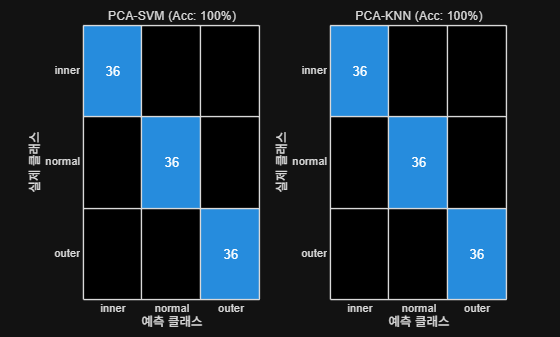

            Method            NumOfFeatures    Accuracy
    ______________________    _____________    ________

    {'SVM + All Features'}         42           91.667 
    {'KNN + All Features'}         42              100 
    {'SVM + SFS'         }          4              100 
    {'KNN + SFS'         }          4              100 
    {'SVM + PCA'         }          6              100 
    {'KNN + PCA'         }          6              100 



    svm_accuracy_select * 100;
    knn_accuracy_select * 100;
    acc_svm;
    acc_knn
    ];

SummaryTable = table(Method, NumOfFeatures, Accuracy);

disp(SummaryTable);

## Discussion 

1. Result of KNN and SVM with all features

When using all features for classification, SVM shows approximately 87–91% accuracy, while KNN achieves 100% accuracy. The SVM classifier may require further improvement through feature selection. The KNN classifier also has the potential risk of overfitting, especially if some features are highly correlated with each other.

2. Result of Feature Selecting(SFS)

Sequential Feature Selection (SFS) was applied for feature selection. During the elimination process, the criterion value remained close to zero, which indicates that many features are highly correlated. Therefore, around 3–5 features are sufficient for training the model. As a result, the accuracy of the SVM classifier increased from 87% to 100%, and KNN maintained its 100% accuracy even with the reduced feature set.

3. Result of Feature Reduction(PCA)

Using PCA, the original 42 features were reduced to 4 principal components while still retaining 96% of the total variance. Reducing the number of features speeds up training and helps remove noise. As a result, both SVM and KNN achieved 100% accuracy on the test dataset with the PCA-reduced features.

### Conclusion

Feature analysis is crucial for achieving accurate classification results. Feature selection helps prevent overfitting by removing redundant or correlated features. With sufficient domain knowledge, it is possible to identify features that are especially important in industrial processes. Feature reduction techniques such as PCA lower the dimensionality of the data, making the model lighter and more efficient. This is beneficial for real-time systems because feature reduction preserves most of the original information while eliminating noise.